DOA = FunctionsOfDOA();
coef = 0.5; % unit distance between sensors divided by the wavelength of the signal

input = [0 3 3];        % [nested_array M1 M2]
% input = [1 2 3];      % [coprime_array M1 M2]
% input = [2 4 3];      % [super_nested_array M1 M2]
% input = [3 4 4 3];    % [augmented_nested_array_1 M1 M2 L1]
% input = [4 7 4];      % [augmented_nested_array_2 M1 M2]
% input = [5 3 3];        % [nested_array_v2 M1 M2]

if input(1) ~= 1
    M = sum(input(2:3))                                     % # of sensors
else
    M = 2 * input(2) - 1 + input(3)
end

M = 6

sensor_locations = DOA.Sensor_Locations(input)                  % sensor locations

sensor_locations =      1     2     3     4     9    13


sensor_placement = DOA.Sensor_Placement(sensor_locations)       % sensor places (in order to visualize the array)

sensor_placement =      1     1     1     1     0     0     0     0     1     0     0     0     1


diff_coarray = DOA.Diff_Coarray(sensor_placement)               % difference coarray

diff_coarray =      1     1     1     1     1     1     1     1     1     1     2     3     6     3     2     1     1     1     1     1     1     1     1     1     1


uDOF = DOA.Uniform_Degrees_Of_Freedom(diff_coarray)             % uniform degrees of freedom

uDOF = 25

LuDOF = DOA.One_Side_Uniform_Degrees_Of_Freedom(diff_coarray)   % one side uniform degrees of freedom

LuDOF = 12

Now, let's use the calculated sensor_locations to compute the array pattern

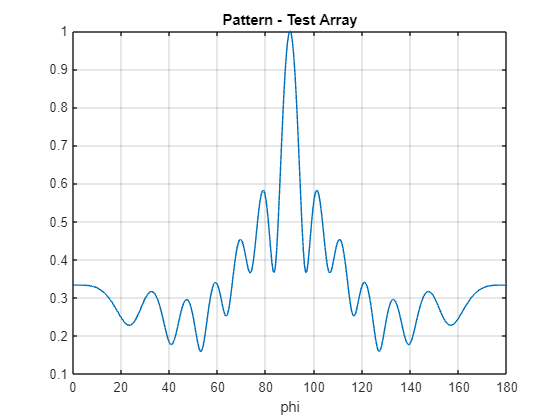

DOA.Array_Pattern(sensor_locations, coef)

and solve an example DOA problem

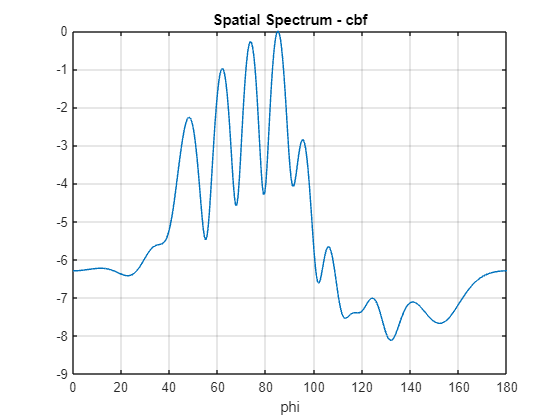

% doa = sort(randi(179, 1, 2));
% doa = [50 150];
doa = 90 - asind(0:0.2:0.6) - 5;                            % source angles
snapshots = 1000;                                           % # of snapshots
SNR_dB = 0;                                                 % signal to noise ratio in decibels
C = DOA.Mutual_Coupling(100, 0.1, M, sensor_locations);         % mutual coupling

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "cbf", C);

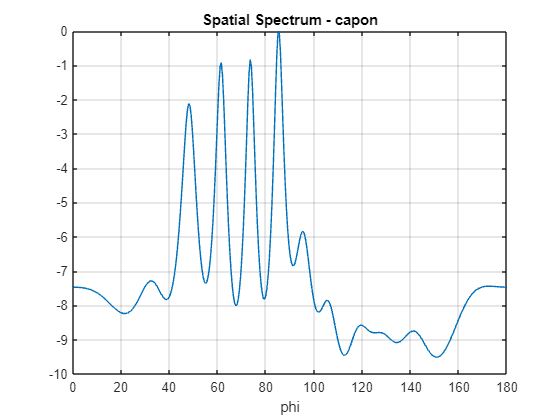

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "capon", C);

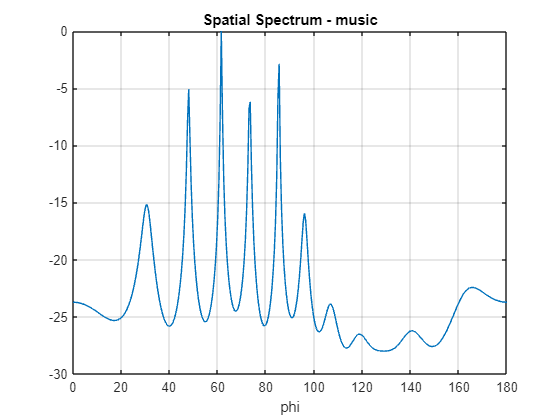

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "music", C);

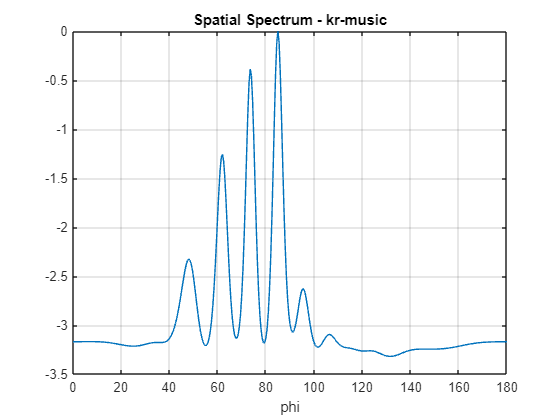

DOA.Spatial_Spectrum(M, sensor_locations, doa, snapshots, SNR_dB, coef, "kr-music", C);

#### Testing Area

Spatial Smoothing is tried here but not achieved yet.

n = length(doa);
N = 1000;
SNR = 0;
M_v = sensor_locations(end);

s = zeros(n, N);
theta = 180 * rand(n, 1);
for i = 1:n
    s(i, :) = exp(1i * 2 * pi * coef * (0:N-1) * cosd(theta(i)));
end
v = (1 / 10^(SNR/10)) * (1/sqrt(2)) * (randn(M, N) + 1i * randn(M, N));

A = zeros(M, n);
for i = 1:n
    A(:, i) = exp(1i * 2 * pi * coef * sensor_locations.' * cosd(doa(i)));
end

y = C * A * s + v;
Ry = (1 / N) * (y * y');
z = Ry(:);

A_d = DOA.khatri_rao(conj(A), A);
p = zeros(n, 1);
for i = 1:n
    p(i) = var(s(i, :));
end

one_v = eye(M); one_v = one_v(:);
sigma_v = 0;
for i = 1:M
    sigma_v = sigma_v + (1 / M) * var(v(i, :));
end

z_ = A_d * p + sigma_v * one_v;

A1 = DOA.Sort_According_to_Sensor_Locations(DOA.Discard_Repeating_Rows(A_d));
e = zeros(2 * M_v - 1, 1); e(M_v) = 1;

z1 = A1 * p + sigma_v * e;
R_z1 = zeros(M_v);
for i = 1:M_v
    z1_i = z1(i:i + M_v - 1);
    R_z1 = R_z1 + (1 / M_v) * (z1_i * z1_i');
end
R_z1

R_z1 =    6.2013 + 0.0000i   0.7593 - 3.3768i  -1.0731 + 0.2670i   1.1525 + 0.0420i  -1.1359 - 1.6667i  -3.1428 + 2.1488i   1.1175 + 0.3554i  -2.3652 - 2.5335i  -2.7633 + 2.2149i   1.2637 + 1.4291i   0.6354 - 2.9487i  -0.9349 + 0.6333i
   0.7593 + 3.3768i   6.9892 + 0.0000i   0.8756 - 3.7861i  -0.9568 + 0.3884i   1.3660 - 0.0677i  -1.6988 - 2.2915i  -2.9535 + 2.1994i   1.5042 - 0.4815i  -2.6027 - 2.7040i  -2.7876 + 2.1401i   1.9714 + 1.3168i   0.6354 - 2.9487i
  -1.0731 - 0.2670i   0.8756 + 3.7861i   6.5673 + 0.0000i   0.8409 - 3.7783i  -0.6792 + 0.2962i   1.1409 - 1.1489i  -1.8600 - 2.1133i  -2.0452 + 1.6352i   1.3502 - 0.6981i  -2.6547 - 2.6020i  -2.7876 + 2.1401i   1.2637 + 1.4291i
   1.1525 - 0.0420i  -0.9568 - 0.3884i   0.8409 + 3.7783i   6.5953 + 0.0000i   0.8320 - 3.8447i  -0.9261 + 0.3531i   1.1873 - 1.1543i  -2.0085 - 2.3306i  -2.1103 + 1.6703i   1.3502 - 0.6981i  -2.6027 - 2.7040i  -2.7633 + 2.2149i
  -1.1359 + 1.6667i   1.3660 + 0.0677i  -0.6792 - 0.2962i   0.8320 + 3.8447i 

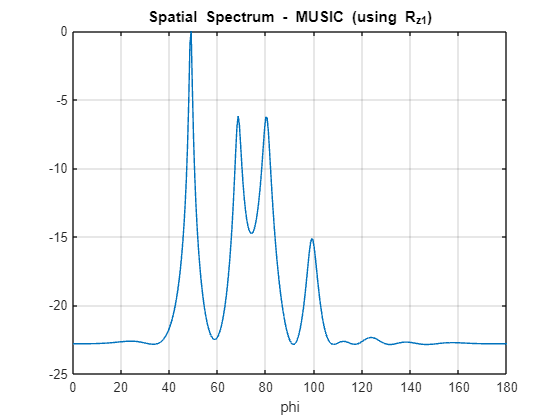

DOA.MUSIC(n, coef, R_z1);

doa

doa =    85.0000   73.4630   61.4218   48.1301
